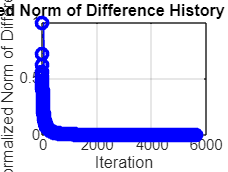

clear; clc; close all;
% Set up initial conditions
M = 0.5;
T_inf = 300;
P_inf = 1e5;
gamma = 1.4; 
Cp_air = 1000;
R = 287;
P = P_inf;
chord = 1;
B = 1 - M^2;
V_inf = 173.55; % M * sqrt(gamma * R * T_inf);
To = T_inf * (1 + (gamma - 1) / 2 * M^2);

% Initialize grid parameters
nx = 141; % Number of x points
ny = 51;  % Number of y points

% Initialize x and y grids
x_grid = zeros(nx, ny);
y_grid = zeros(nx, ny);

% Set up the x-values of the grid with stretching
dx = 0.025; % Initial dx
growth = 1.1;
dx_dyn = dx;
x_cur = 0;

for i = 1:nx
    if i >= 1 && i <= 50
        % Left side of x=0, decreasing x-values with stretching
        point = 51 - i;
        x_grid(point, :) = x_cur - dx_dyn;
        x_cur = x_grid(point, 1);
        dx_dyn = dx_dyn * growth;
        
    elseif i == 51
        % x = 0
        x_grid(51, :) = 0;
        x_cur = 0;
        dx_dyn = dx; % Reset dx_dyn for right side

    elseif i >= 52 && i <= 91
        % x increases by constant dx
        x_grid(i, :) = x_cur + dx;
        x_cur = x_grid(i, 1);
        % No change in dx_dyn here since dx is constant

    elseif i >= 92
        % x increases with stretching
        x_grid(i, :) = x_cur + dx_dyn;
        x_cur = x_grid(i, 1);
        dx_dyn = dx_dyn * growth;
    end
end


% Set up the y-values of the grid with stretching
dy = 0.025;
growth_y = 1.1;

% Compute the y-values using the formula for the sum of a geometric series
j = 1:ny;
y_p = dy * (growth_y.^j - 1) / (growth_y - 1);

% Create the y_grid by repeating y_p over nx rows
y_grid = repmat(y_p, nx, 1);


% Calculate initial phi
phi_old = V_inf * x_grid;

% Calculate dy/dx for the airfoil boundary
dy_dx = zeros(nx, 1);
for i = 1:nx
    x_foil = x_grid(i, 1);
    if i >= 50 && i <= 91
        dy_dx(i) = ((69.722 - x_foil^2 + x_foil - 0.25)^(-0.5)) * (-x_foil + 0.5);
    else
        dy_dx(i) = 0;
    end
end

% Apply boundary conditions at the airfoil surface
for i = 1:nx
    phi_old(i, 1) = phi_old(i, 2) - (y_grid(i, 2) - y_grid(i, 1)) * V_inf * dy_dx(i);
end
% Set boundary conditions at far fields
phi_old(1, :) = V_inf * x_grid(1, :);
phi_old(end, :) = V_inf * x_grid(end, :);


% Initialize deltas for variable grid spacing
del_x_plus = zeros(nx, ny);
del_x_minus = zeros(nx, ny);
del_x_o = zeros(nx, ny);
del_y_plus = zeros(nx, ny);
del_y_minus = zeros(nx, ny);
del_y_o = zeros(nx, ny);

% Initialize coefficients for finite difference equation
a_coef = zeros(nx, ny);
b = zeros(nx, ny);
d = zeros(nx, ny);
e = zeros(nx, ny);
f_coef = zeros(nx, ny);

% Compute deltas in x-direction
for i = 2:nx-1
    for j = 2:ny-1
        del_x_plus(i, j) = x_grid(i+1, j) - x_grid(i, j);
        del_x_minus(i, j) = x_grid(i, j) - x_grid(i-1, j);
        del_x_o(i, j) = (x_grid(i+1, j) - x_grid(i-1, j)) / 2;
    end
end

% Compute deltas in y-direction
for i = 2:nx-1
    for j = 2:ny-1
        del_y_plus(i, j) = y_grid(i, j+1) - y_grid(i, j);
        del_y_minus(i, j) = y_grid(i, j) - y_grid(i, j-1);
        del_y_o(i, j) = (y_grid(i, j+1) - y_grid(i, j-1)) / 2;
    end
end

% Compute coefficients
for i = 2:nx-1
    for j = 2:ny-1
        d(i, j) = (B * del_y_o(i, j) / del_x_plus(i, j)) + (B * del_y_o(i, j) / del_x_minus(i, j)) + (del_x_o(i, j) / del_y_plus(i, j)) + (del_x_o(i, j) / del_y_minus(i, j));
        b(i, j) = -B * del_y_o(i, j) / del_x_minus(i, j);
        a_coef(i, j) = -B * del_y_o(i, j) / del_x_plus(i, j);
        f_coef(i, j) = -del_x_o(i, j) / del_y_minus(i, j);
        e(i, j) = -del_x_o(i, j) / del_y_plus(i, j);
    end
end

% Initialize iteration parameters
Iteration_num = 10000;
residual = zeros(1, Iteration_num);
w = 1.5; % Relaxation parameter
phi_new = phi_old;
tolerance = 1e-3;

% Iterative solver
for k = 1:Iteration_num
    phi_old_prev = phi_old;
    % Update interior points
    for i = 2:nx-1
        for j = 2:ny-1
            phi_new(i, j) = ((phi_new(i-1, j) * (-b(i, j))) + (phi_old(i+1, j) * (-a_coef(i, j))) + (phi_new(i, j-1) * (-f_coef(i, j))) + (phi_old(i, j+1) * (-e(i, j)))) / d(i, j);
        end
    end
    % Apply boundary conditions at the airfoil surface
    for i = 1:nx
        phi_new(i, 1) = phi_new(i, 2) - (y_grid(i, 2) - y_grid(i, 1)) * V_inf * dy_dx(i);
    end
    % Apply boundary conditions at far fields
    phi_new(1, :) = V_inf * x_grid(1, :);
    phi_new(end, :) = V_inf * x_grid(end, :);
    % Over-relaxation
    phi_new = phi_old + w * (phi_new - phi_old);
    % Compute residual
    del_e = norm(phi_new - phi_old_prev);

    if k == 1
        del_0 = del_e;
    end
    residual(k) = del_e / del_0;
    phi_old = phi_new;
    % Check for convergence
    if residual(k) < tolerance
        residual = residual(1:k);
        break;
    end
end

% Post-processing
% Calculate u and v velocities
u = zeros(nx, ny);
v = zeros(nx, ny);

% Compute u velocities
for i = 2:nx-1
    for j = 1:ny
        u(i, j) = (phi_new(i+1, j) - phi_new(i-1, j)) / (x_grid(i+1, j) - x_grid(i-1, j));
    end
end
% Left and right boundaries
u(1, :) = (phi_new(2, :) - phi_new(1, :)) / (x_grid(2, :) - x_grid(1, :));
u(end, :) = (phi_new(end, :) - phi_new(end-1, :)) / (x_grid(end, :) - x_grid(end-1, :));

% Compute v velocities
for i = 1:nx
    for j = 2:ny-1
        v(i, j) = (phi_new(i, j+1) - phi_new(i, j-1)) / (y_grid(i, j+1) - y_grid(i, j-1));
    end
end
% Bottom and top boundaries
v(:, 1) = (phi_new(:, 2) - phi_new(:, 1)) / (y_grid(1, 2) - y_grid(1, 1));
v(:, end) = (phi_new(:, end) - phi_new(:, end-1)) / (y_grid(1, end) - y_grid(1, end-1));

% Calculate pressure coefficient Cp along the airfoil boundary
Cpu = u(50:91, 1); Cpv = v(50:91, 1);
p = P_inf * (1 - (gamma - 1) / 2 * M^2 * (((Cpu.^2 + Cpv.^2) / V_inf^2) - 1)).^(gamma / (gamma - 1));
Cp = (p - P_inf) / (0.5 * gamma * P_inf * M^2);

% Plotting residuals vs iteration
figure;
plot(1:length(residual), residual, '-o', 'LineWidth', 2, 'MarkerSize', 6, 'Color', 'b');
xlabel('Iteration');
ylabel('Normalized Norm of Difference');
title('Normalized Norm of Difference History vs. Iteration');
grid on;

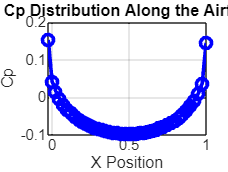


% Plot Cp distribution along the airfoil boundary
x_airfoil = x_grid(50:91, 1);
figure;
plot(x_airfoil, Cp, '-o', 'LineWidth', 2, 'MarkerSize', 6, 'Color', 'b');
xlabel('X Position');
ylabel('Cp');
title('Cp Distribution Along the Airfoil');
grid on;

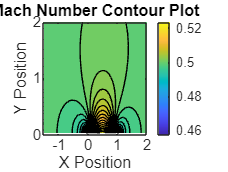


% Calculate Mach number distribution
V = sqrt(u.^2 + v.^2);
T = To - V.^2 / (2 * Cp_air);
a = sqrt(gamma * R .* T);
M_list = V ./ a;

% Plot Mach number contour
figure;
contourf(x_grid, y_grid, M_list, 40);
colorbar;
xlabel('X Position');
ylabel('Y Position');
title('Mach Number Contour Plot');
xlim([-1.5 2])
ylim([0 2])